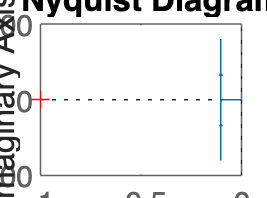

sys_open = tf(1.6048, [0.0640 1 0],'InputDelay', 0);
l = linspace(0, 1000, 100000);
h = nyquistplot(sys_open, l);


S = allmargin(sys_open)

S = struct with fields:
     GainMargin: Inf
    GMFrequency: Inf
    PhaseMargin: 84.1667
    PMFrequency: 1.5963
    DelayMargin: 0.9202
    DMFrequency: 1.5963
         Stable: 1


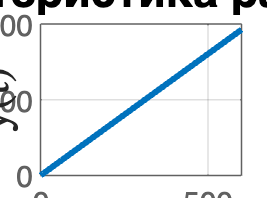


step(sys_open)
set(findall(gcf, 'type', 'line'), 'linewidth', 2);
grid on;
ylabel('y(t)', 'Interpreter', 'latex', 'FontSize', 15);
title('Переходная характеристика разомкнутой системы','FontSize', 15);

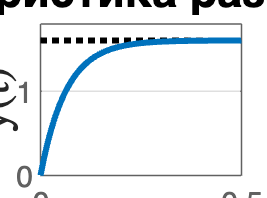


impulse(sys_open)
set(findall(gcf, 'type', 'line'), 'linewidth', 2);
grid on;
ylabel('y(t)', 'Interpreter', 'latex', 'FontSize', 15);
title('Весовая характеристика разомкнутой системы','FontSize', 15);